This is an example of an isetauto scene. It has object instances.

I am comparing dev and dev-resources branch renderings of the scene.

So for, the two branches on the taxi scene when there is only one taxi.

ieInit;
if ~piDockerExists, piDockerConfig; end

## This rendering seems to match on dev and dev-resources

system('git checkout dev');

M	tutorials/underDevelopment/t_TestZhenyi.mlx
Already on 'dev'
Your branch is up to date with 'origin/dev'.



chdir(piRootPath);
addpath(genpath(pwd));

fileName = fullfile(piRootPath, 'data/scenes/low-poly-taxi/low-poly-taxi.pbrt');
thisR = piRead(fileName);

Read 12 materials and 0 textures..


thisR.set('skymap',fullfile(piRootPath,'data/skymaps','sky-rainbow.exr'));

Using skymap:  /Users/wandell/Documents/MATLAB/iset3d-v4/data/skymaps/sky-rainbow.exr



piWrite(thisR);
thisR.show('objects');


----- Summary of recipe: recipe

                                index       material           positions (m)              sizes (m)       
                                _____    _______________    ____________________    ______________________

    001_001_Plane_O               4      {'Material'   }    {'0.00 0.00 0.00'  }    {'165.41 165.41 0.00'}
    001_001_car-body.002_O        8      {'Bumper'     }    {'0.50 1.34 0.78'  }    {'0.12 0.05 0.04'    }
    002_001_car-body.003_O       11      {'Black'      }    {'0.01 1.39 0.68'  }    {'0.09 0.08 0.07'    }
    003_001_Cube_O               14      {'taxi_head'  }    {'-0.02 -0.26 1.29'}    {'0.22 0.08 0.13'    }
    001_Cube.001_O               17      {'Bumper'     }    {'-0.00 1.22 0.54' }    {'1.45 0.37 0.26' 


scene = piWRS(thisR);

Started Docker (status 0): docker  --context remote-mux run -d -it  --gpus device=0  --name pbrt-gpu-wandell15211  -v /home/wandell/iset/iset3d-v4/local:/iset/iset3d-v4/local  digitalprodev/pbrt-v4-gpu-ampere-mux:latest bash
Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/low-poly-taxi/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/low-poly-taxi/ ...
Done (0.59 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell15211 sh -c "cd /iset/iset3d-v4/local/low-poly-taxi && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/low-poly-taxi.exr low-poly-taxi.pbrt"
Rendered remotely in: 43.92 sec
Pull: rsync -r  wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/low-poly-taxi/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/low-poly-taxi/renderings ...
done (  0.73 sec)

------------------
Container command: docker --context remote-mux exec -it  pbrt-gpu-wande

ip = piRadiance2RGB(scene,'etime',1/30);

eT: 33.333333 ms 


ipSet('ip','name','dev');
ipWindow(ip);

ipSet(ip,'gamma',0.5);

system('git branch --show-current');

dev


## Change branch and run again

system('git checkout dev-resources');

error: Your local changes to the following files would be overwritten by checkout:
	tutorials/underDevelopment/t_TestZhenyi.mlx
Please commit your changes or stash them before you switch branches.
Aborting



chdir(piRootPath);
addpath(genpath(pwd));

fileName = fullfile(piRootPath, 'data/scenes/low-poly-taxi/low-poly-taxi.pbrt');
thisR = piRead(fileName);

Read 12 materials and 0 textures..


thisR.set('skymap',fullfile(piRootPath,'data/skymaps','sky-rainbow.exr'));

piWrite(thisR);
thisR.show('objects');


----- Summary of recipe: recipe

                                index       material           positions (m)              sizes (m)       
                                _____    _______________    ____________________    ______________________

    001_001_Plane_O               4      {'Material'   }    {'0.00 0.00 0.00'  }    {'165.41 165.41 0.00'}
    001_001_car-body.002_O        8      {'Bumper'     }    {'0.50 1.34 0.78'  }    {'0.12 0.05 0.04'    }
    002_001_car-body.003_O       11      {'Black'      }    {'0.01 1.39 0.68'  }    {'0.09 0.08 0.07'    }
    003_001_Cube_O               14      {'taxi_head'  }    {'-0.02 -0.26 1.29'}    {'0.22 0.08 0.13'    }
    001_Cube.001_O               17      {'Bumper'     }    {'-0.00 1.22 0.54' }    {'1.45 0.37 0.26' 

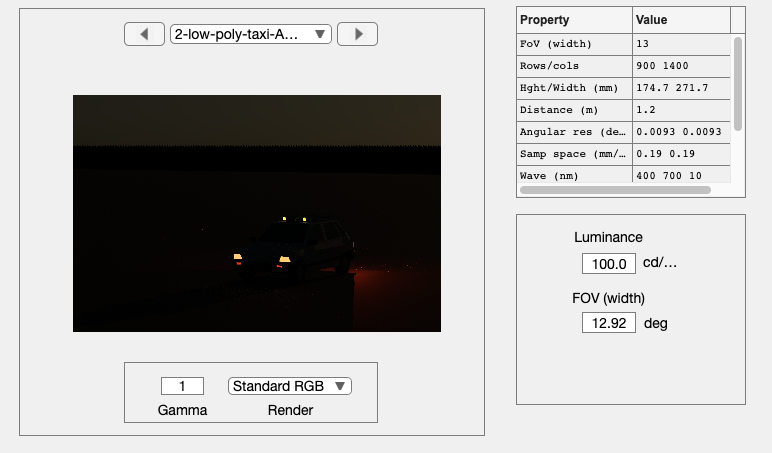

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/low-poly-taxi/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/low-poly-taxi/ ...
Done (0.39 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell15211 sh -c "cd /iset/iset3d-v4/local/low-poly-taxi && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/low-poly-taxi.exr low-poly-taxi.pbrt"
Rendered remotely in: 13.66 sec
Pull: rsync -r  wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/low-poly-taxi/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/low-poly-taxi/renderings ...
done (  0.74 sec)

------------------
Container command: docker --context remote-mux exec -it  pbrt-gpu-wandell15211 sh -c "cd /iset/iset3d-v4/local/low-poly-taxi && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/low-poly-taxi.exr low-poly-taxi.pbrt"
PBRT command: pbrt --gpu --outfile renderings/low-poly-taxi.exr low-p


scene = piWRS(thisR);

ip = piRadiance2RGB(scene,'etime',1/30);

eT: 33.333333 ms 


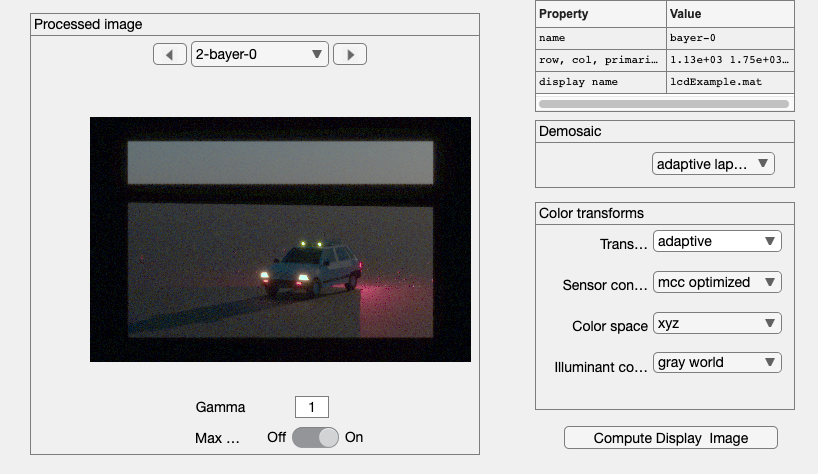

ipSet('ip','name','dev-resources');
ipWindow(ip);

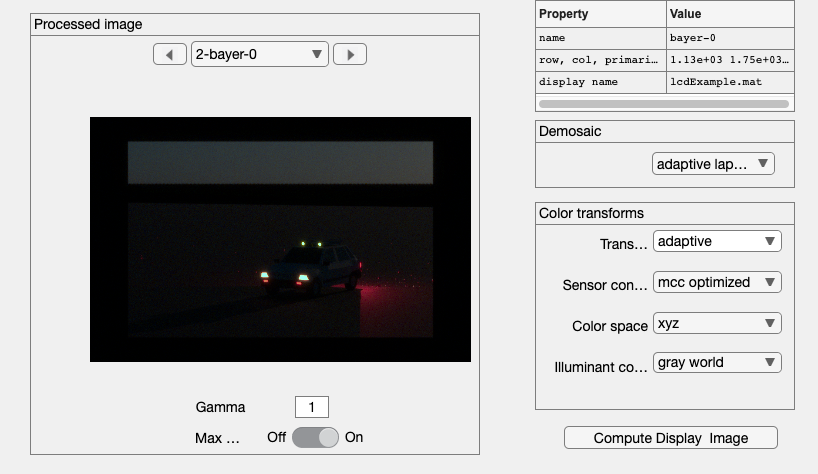

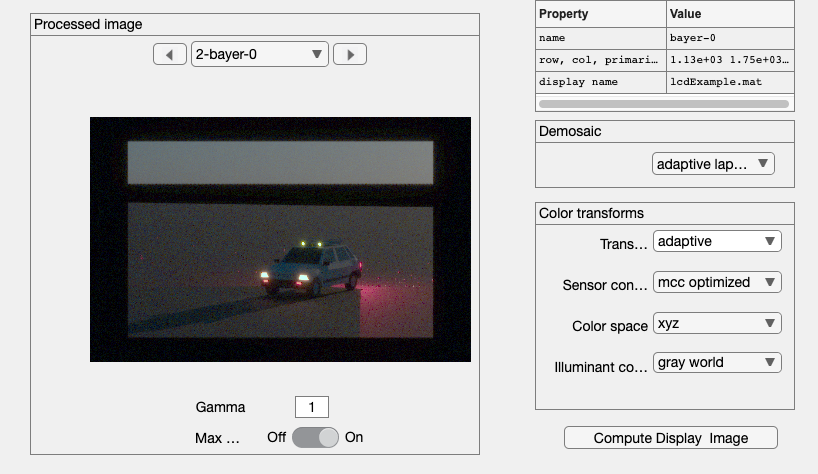

ipSet(ip,'gamma',0.5);


system('git branch --show-current');

dev


## Add a second car.  This checks the instancing.

system('git checkout dev');

carName = 'taxi';

rotationMatrix = piRotationMatrix('z', -15);
position       = [-4 0 0];

thisR   = piObjectInstanceCreate(thisR, [carName,'_m_B'], ...
    'rotation',rotationMatrix, 'position',position);
thisR.assets = thisR.assets.uniqueNames;

scene = piWRS(thisR);

ip = piRadiance2RGB(scene,'etime',1/30);

ipWindow(ip);